if ~exist('data/chap05', 'dir')
    gunzip('https://github.com/sp-au-mu-nl/SpeechComm/raw/refs/heads/main/data/chap05.zip','data')
    unzip('data/chap05.zip', 'data/chap05/')
end

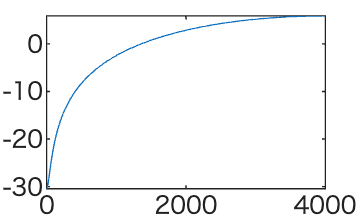

sr = 8000; nFFT = 512;
f = linspace(0,sr/2,nFFT/2+1);
p = 0.97;
S = fft([1, -p], nFFT);
plot(f, 20*log10(abs(S(1:nFFT/2+1))))

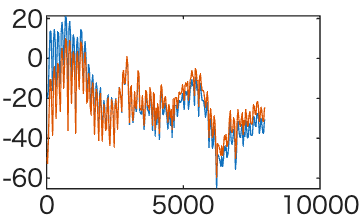

[ySa, sr] = audioread('data/chap05/sa48k.wav');
ySa = resample(ySa, 16000, sr);
sr = 16000;

nFFT = 512;
SSa = fft(ySa(7500+(1:nFFT)).*hann(nFFT));
ySaEmphasis = filter([1 -p], 1, ySa);
SSaEmphasis = fft(ySaEmphasis(7500+(1:nFFT)).*hann(nFFT));
frequency = linspace(0,sr/2,nFFT/2+1);
plot(frequency, 20*log10(abs(SSa(1:nFFT/2+1)))); hold on
plot(frequency, 20*log10(abs(SSaEmphasis(1:nFFT/2+1)))); hold off

プログラム 5.2

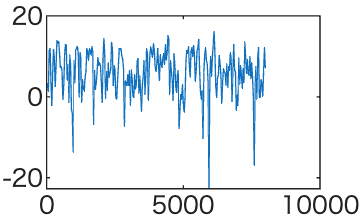

sr = 16000;
t = 0:1/sr:1;
r = randn(size(t));
r = r/max(abs(r))/1.01;
nFFT = 512;
SR = fft(r(1:nFFT)'.*hann(nFFT));
frequency = linspace(0,sr/2,nFFT/2+1);
plot(frequency, 20*log10(abs(SR(1:nFFT/2+1))));

プログラム 5.3

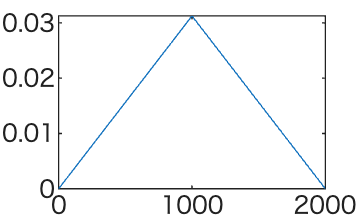

nWindow = nFFT/8;
windowInc = linspace(0, 1, nWindow/2+1);
windowDec = linspace(1, 0, nWindow/2+1);
windowTri = [windowInc windowDec(2:end)];
windowTriNormalized = windowTri/sum(windowTri);
plot(frequency(1:length(windowTriNormalized)), windowTriNormalized)

プログラム 5.4

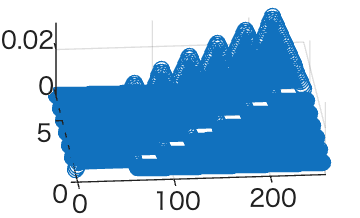

center = nWindow/2+1:nWindow/2:nFFT/2;
filterBank = zeros(length(center), nFFT/2+1);
for iFilter = 1:length(center)
    iStart = center(iFilter) - nWindow/2;
    filterBank(iFilter, iStart:(iStart+nWindow)) = windowTriNormalized;
end

stem3(filterBank);
view([-5 50])

プログラム 5.5

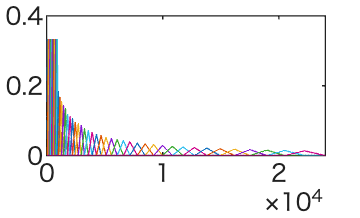

sr = 48000;

nFFT = 2048;
nBank = 48;
upper = sr/2;
lower = 0;
frequency = linspace(0, sr/2, nFFT/2+1);
melFilterBank = zeros(nBank, nFFT/2+1);
nMelWindowLow = round(400/3/(sr/nFFT));
if mod(nMelWindowLow, 2) ~= 0
    nMelWindowLow = nMelWindowLow + 1; % Ensure it's even
end
windowMelIncLow = linspace(0, 1, nMelWindowLow/2+1);
windowMelDecLow = linspace(1, 0, nMelWindowLow/2+1);
windowMelTriLow = [windowMelIncLow windowMelDecLow(2:end)];
windowMelTriLowNormalized = windowMelTriLow/sum(windowMelTriLow);
centerLow = nMelWindowLow/2:nMelWindowLow/2:13*nMelWindowLow/2;
for iCenterLow = 1:length(centerLow)
    start = centerLow(iCenterLow)-nMelWindowLow/2;
    melFilterBank(iCenterLow, start+(1:nMelWindowLow+1)) = ...
        windowMelTriLowNormalized;
end

upperMel = hz2mel(upper);
lowerMel = hz2mel(frequency(centerLow(end)));
stepMel = (upperMel-lowerMel)/(nBank+1-length(centerLow));
center = round(mel2hz(lowerMel:stepMel:upperMel)/(sr/2)*(nFFT/2))+1;
for iCenter = 1:length(center)-2
    t0 = center(iCenter); t1 = center(iCenter+1); t2 = center(iCenter+2);
    iCurrent = iCenterLow+iCenter+1;
    melFilterBank(iCurrent, t0:t1) = linspace(0, 1, t1-t0+1);
    melFilterBank(iCurrent, t1:t2) = linspace(1, 0, t2-t1+1);
    melFilterBank(iCurrent, :) = melFilterBank(iCurrent, :) / ...
        sum(melFilterBank(iCurrent, :));
end

plot(frequency, melFilterBank')

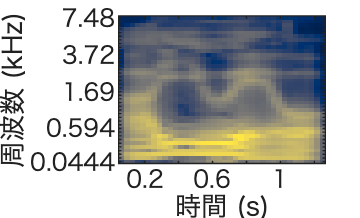

[y, sr] = audioread('data/chap05/aiueo16k.wav');
nBank = 40;
melSpectrogram(y, sr, "Window",hann(2048), ...
    "OverlapLength",2048-512,"FFTLength",2048,...
    "NumBands",nBank,"FrequencyRange",[0 8000]); % パラメタは、librosa の規定値に合わせた
colorbar off

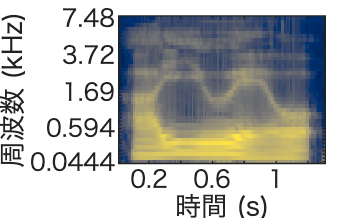

melSpectrogram(y, sr, "NumBands",nBank)
colorbar off

function mel = hz2mel(freq)
    mel = 1127 * log(1+freq/700);
end

function freq = mel2hz(mel)
    freq = (exp(mel/1127)-1)*700;
end